# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 28-Oct-2019 19:31:47

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Temp"];
opts.VariableTypes = ["datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "InputFormat", "yyyy-MM-dd");

% Import the data
mintemps = readtable("C:\Users\darrahts\Dropbox\timeSeriesAnalysis\datasets\daily-min-temperatures.csv", opts)

mintemps = 3650×2 table
       Date       Temp
    __________    ____

    1981-01-01    20.7
    1981-01-02    17.9
    1981-01-03    18.8
    1981-01-04    14.6
    1981-01-05    15.8
    1981-01-06    15.8
    1981-01-07    15.8
    1981-01-08    17.4
    1981-01-09    21.8
    1981-01-10      20
    1981-01-11    16.2
    1981-01-12    13.3
    1981-01-13    16.7
    1981-01-14    21.5
    1981-01-15      25
    1981-01-16    20.7


## Clear temporary variables

clear opts

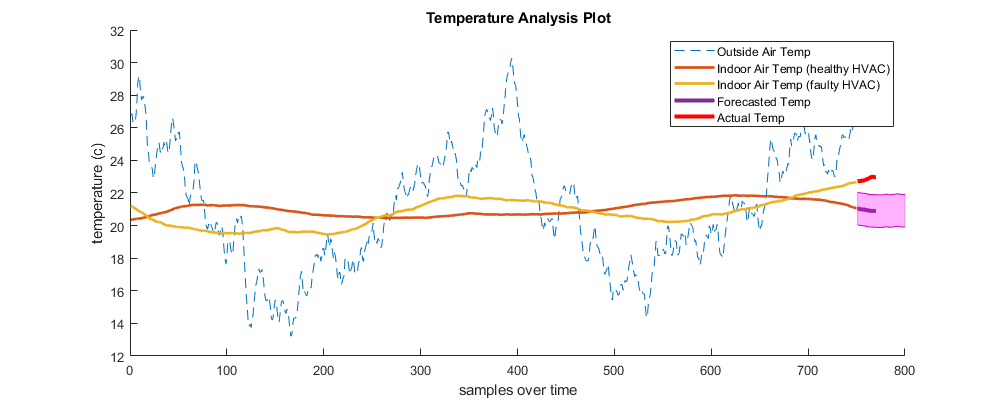

f1 = figure(1); clf;
f1.Position = [0 0 1000 400];
nominal = smoothdata(mintemps.Temp(400:1220), 'movmean', 700);
faulty = smoothdata(mintemps.Temp(400:1220), 'movmean', 300);
x = (751:800);
topBound = (nominal(x)+11)';
lowBound = (nominal(x)+9)';
hold on;
plot(smoothdata(mintemps.Temp(400:1149), 'movmean', 10)+10, '--');
plot(nominal(1:750)+10, 'linew', 2);
plot(faulty(1:750)+10, 'linew', 2);
plot((751:770),nominal(751:770)+10, 'linew', 3);
plot((751:770), (faulty(751:770)+10), 'r', 'linew', 3);
plot([x],lowBound, 'm');
plot([x],topBound, 'm');
fill([x,fliplr(x)], [topBound, fliplr(lowBound)], 'm', 'EdgeAlpha', .2, "FaceAlpha", .3);



hold off;
title("Temperature Analysis Plot");
xlabel("samples over time");
ylabel("temperature (c)");
legend(["Outside Air Temp", "Indoor Air Temp (healthy HVAC)", "Indoor Air Temp (faulty HVAC)", "Forecasted Temp","Actual Temp"]);